### Importing Cleaned Level 1 Data

#### Start Times

opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A1:D215500";

% Specify column names and types
opts.VariableNames = ["timeBegin", "durations", "Var3", "DateAndTime"];
opts.SelectedVariableNames = ["timeBegin", "durations", "DateAndTime"];
opts.VariableTypes = ["datetime", "double", "char", "datetime"];

% Specify variable properties
opts = setvaropts(opts, "Var3", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var3", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "timeBegin", "InputFormat", "");
opts = setvaropts(opts, "DateAndTime", "InputFormat", "");

% Import the data
level1cleanedAB = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\level1_cleaned_AB.xlsx", opts, "UseExcel", false)

level1cleanedAB = 215500×3 table
         timeBegin          durations        DateAndTime     
    ____________________    _________    ____________________

                     NaT         NaN                      NaT
    01-Jan-2010 11:30:00    0.076389     01-Jan-2010 11:30:00
    02-Jan-2010 11:30:00    0.020833     02-Jan-2010 11:30:00
    05-Jan-2010 16:40:00    0.055556     05-Jan-2010 16:40:00
    05-Jan-2010 20:20:00    0.027778     05-Jan-2010 20:20:00
    06-Jan-2010 20:10:00    0.027778     06-Jan-2010 20:10:00
    08-Jan-2010 13:30:00    0.034722     08-Jan-2010 13:30:00
    09-Jan-2010 18:30:00    0.027778     09-Jan-2010 18:30:00
    10-Jan-2010 10:50:00    0.020833     10-Jan-2010 10:50:00
    10-Jan-2010 12:30:00    0.041667     10-Jan-2010 12:30:00
    10-Jan-2010 18:50:00    0.083333     10-Jan-2010 18:50:00
    12-Jan-2010 01:40:00    0.034722     12-Jan-2010 01:40

clear opts
level1cleanedAB(1,:) = []

level1cleanedAB = 215499×3 table
         timeBegin          durations        DateAndTime     
    ____________________    _________    ____________________

    01-Jan-2010 11:30:00    0.076389     01-Jan-2010 11:30:00
    02-Jan-2010 11:30:00    0.020833     02-Jan-2010 11:30:00
    05-Jan-2010 16:40:00    0.055556     05-Jan-2010 16:40:00
    05-Jan-2010 20:20:00    0.027778     05-Jan-2010 20:20:00
    06-Jan-2010 20:10:00    0.027778     06-Jan-2010 20:10:00
    08-Jan-2010 13:30:00    0.034722     08-Jan-2010 13:30:00
    09-Jan-2010 18:30:00    0.027778     09-Jan-2010 18:30:00
    10-Jan-2010 10:50:00    0.020833     10-Jan-2010 10:50:00
    10-Jan-2010 12:30:00    0.041667     10-Jan-2010 12:30:00
    10-Jan-2010 18:50:00    0.083333     10-Jan-2010 18:50:00
    12-Jan-2010 01:40:00    0.034722     12-Jan-2010 01:40:00
    12-Jan-2010 11:00:00    0.034722     12-Jan-2010 11:00


L1_start_times_tstamps = timeofday(level1cleanedAB.timeBegin) %HH:MM:SS format of data

L1_start_times_tstamps = 215499×1 duration array
   11:30:00
   11:30:00
   16:40:00
   20:20:00
   20:10:00
   13:30:00
   18:30:00
   10:50:00
   12:30:00
   18:50:00
   01:40:00
   11:00:00
   22:30:00
   10:30:00
   15:20:00
   17:20:00
   18:20:00
   17:10:00
   08:20:00
   18:00:00
   16:50:00
   20:40:00
   12:40:00
   19:30:00
   15:50:00
   16:50:00
   14:40:00
   16:10:00
   10:00:00
   15:00:00


L1_start_times_mins = minutes(timeofday(level1cleanedAB.timeBegin)) %Start time converted to minutes(total), eg. 11:30 PM To 690 mins

L1_start_times_mins =          690
         690
        1000
        1220
        1210
         810
        1110
         650
         750
        1130



%The distribution fitte app was used and the sesison was saved to level1_start_times.dfit

#### Durations

opts = delimitedTextImportOptions("NumVariables", 1);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = "durations";
opts.VariableTypes = "double";

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
l1durationsxformed = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\l1_durations_xformed.csv", opts)

l1durationsxformed = 215499×1 table
    durations
    _________

       110   
        30   
        80   
        40   
        40   
        50   
        40   
        30   
        60   
       120   
        50   
        50   
        50   
        70   
        90   
        40   


clear opts

### Importing Cleaned Level 2 Data

#### Start Times

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A1:D96498";

% Specify column names and types
opts.VariableNames = ["timeBegin", "durations", "Var3", "timeBegin1"];
opts.SelectedVariableNames = ["timeBegin", "durations", "timeBegin1"];
opts.VariableTypes = ["datetime", "double", "char", "datetime"];

% Specify variable properties
opts = setvaropts(opts, "Var3", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var3", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "timeBegin", "InputFormat", "");
opts = setvaropts(opts, "timeBegin1", "InputFormat", "");

% Import the data
level2cleanedAB = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\level2_cleaned_AB.xlsx", opts, "UseExcel", false);
% Clear temporary variables
clear opts
level2cleanedAB(1,:) = []

level2cleanedAB = 96497×3 table
         timeBegin          durations         timeBegin1     
    ____________________    _________    ____________________

    01-Jan-2010 11:30:00    0.013889     01-Jan-2010 11:30:00
    05-Jan-2010 16:40:00    0.013889     05-Jan-2010 16:40:00
    10-Jan-2010 19:30:00    0.013889     10-Jan-2010 19:30:00
    14-Jan-2010 15:20:00    0.013889     14-Jan-2010 15:20:00
    18-Jan-2010 16:50:00    0.013889     18-Jan-2010 16:50:00
    20-Jan-2010 16:50:00    0.013889     20-Jan-2010 16:50:00
    22-Jan-2010 10:00:00    0.013889     22-Jan-2010 10:00:00
    23-Jan-2010 12:30:00    0.013889     23-Jan-2010 12:30:00
    23-Jan-2010 16:00:00    0.013889     23-Jan-2010 16:00:00
    23-Jan-2010 18:20:00    0.027778     23-Jan-2010 18:20:00
    28-Jan-2010 14:00:00    0.020833     28-Jan-2010 14:00:00
    28-Jan-2010 20:20:00    0.048611     28-Jan-2010 20:20:

L2_start_times_tstamps = timeofday(level2cleanedAB.timeBegin) %HH:MM:SS format of data

L2_start_times_tstamps = 96497×1 duration array
   11:30:00
   16:40:00
   19:30:00
   15:20:00
   16:50:00
   16:50:00
   10:00:00
   12:30:00
   16:00:00
   18:20:00
   14:00:00
   20:20:00
   16:00:00
   19:00:00
   21:20:00
   15:50:00
   10:00:00
   13:50:00
   13:20:00
   16:00:00
   19:30:00
   19:40:00
   16:20:00
   17:10:00
   09:50:00
   11:50:00
   19:30:00
   13:10:00
   13:30:00
   21:20:00


L2_start_times_mins = minutes(timeofday(level2cleanedAB.timeBegin)) %Start time converted to minutes(total), eg. 11:30 PM To 690 mins

L2_start_times_mins =          690
        1000
        1170
         920
        1010
        1010
         600
         750
         960
        1100




%The distribution fitter app was used and the sesison was saved to level2_start_times.dfit

#### Durations

opts = delimitedTextImportOptions("NumVariables", 1);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = "durations";
opts.VariableTypes = "double";

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
l2durationsxformed = readtable("C:\Users\Shankar Ramharack\OneDrive - The University of the West Indies, St. Augustine\Desktop\EV-Grid-Integration-Study\data\l2_durations_xformed.csv", opts)

l2durationsxformed = 96497×1 table
    durations
    _________

        20   
        20   
        20   
        20   
        20   
        20   
        20   
        20   
        20   
        40   
        30   
        70   
        30   
        20   
        30   
       150   


clear opts

### Visualizations

Histograms of the start times are generated below

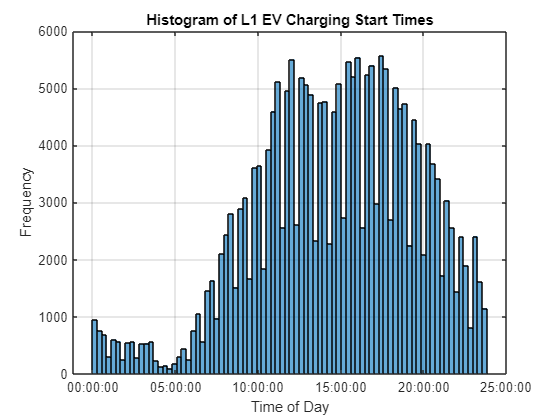

%%Start Times
figure;
histogram(L1_start_times_tstamps)
grid on
title("Histogram of L1 EV Charging Start Times")
xlabel("Time of Day")
ylabel("Frequency")

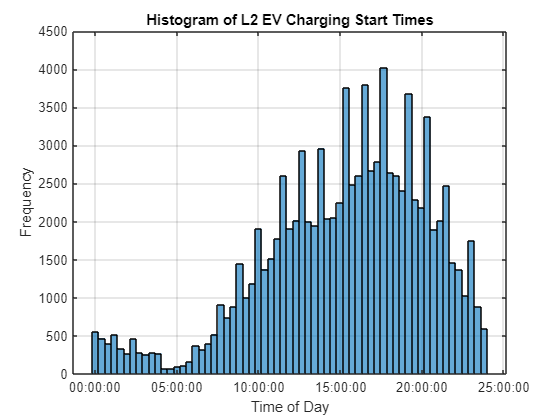

figure;
histogram(L2_start_times_tstamps)
grid on
title("Histogram of L2 EV Charging Start Times")
xlabel("Time of Day")
ylabel("Frequency")

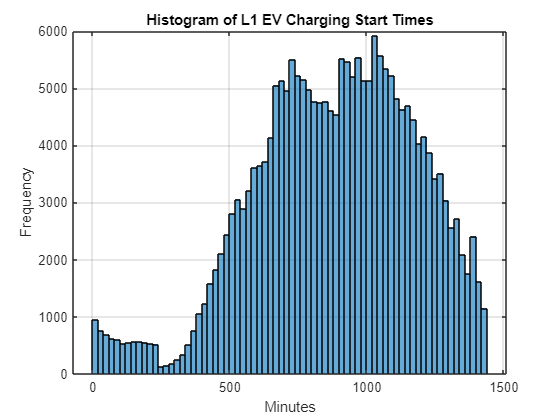

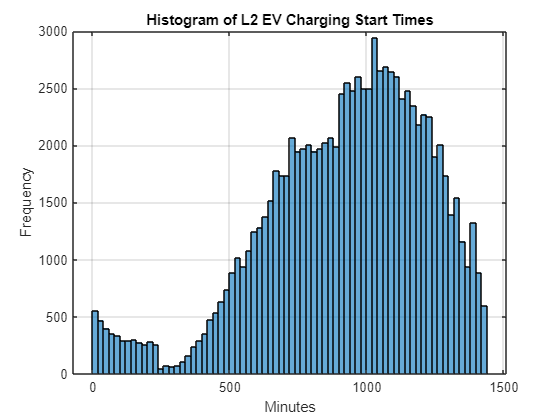




figure;

histogram(L1_start_times_mins)
grid on
title("Histogram of L1 EV Charging Start Times")
xlabel("Minutes")
ylabel("Frequency")
figure;
histogram(L2_start_times_mins)
grid on
title("Histogram of L2 EV Charging Start Times")
xlabel("Minutes")
ylabel("Frequency")

%%Durations
l1_durs = l1durationsxformed.durations

l1_durs =    110
    30
    80
    40
    40
    50
    40
    30
    60
   120


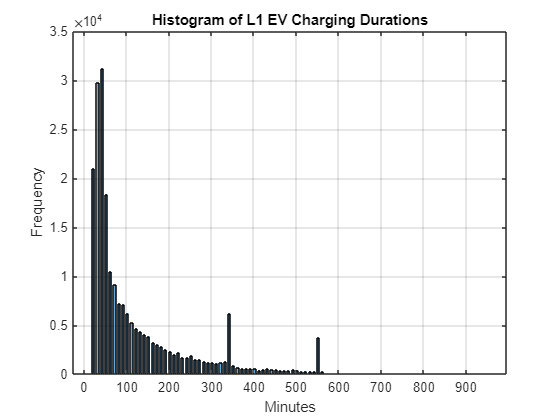

figure;
histogram(l1_durs)
grid on
title("Histogram of L1 EV Charging Durations")
xlabel("Minutes")
ylabel("Frequency")


l2_durs = l2durationsxformed.durations

l2_durs =     20
    20
    20
    20
    20
    20
    20
    20
    20
    40


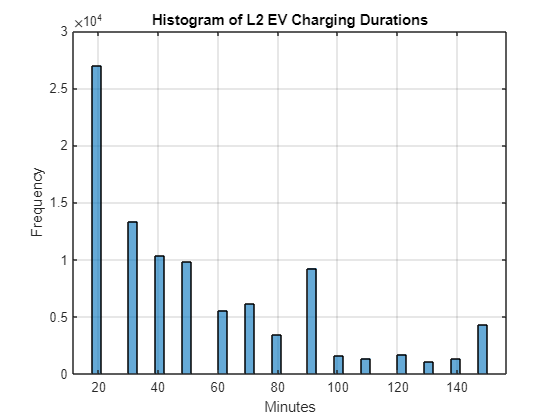

figure;
histogram(l2_durs)
grid on
title("Histogram of L2 EV Charging Durations")
xlabel("Minutes")
ylabel("Frequency")